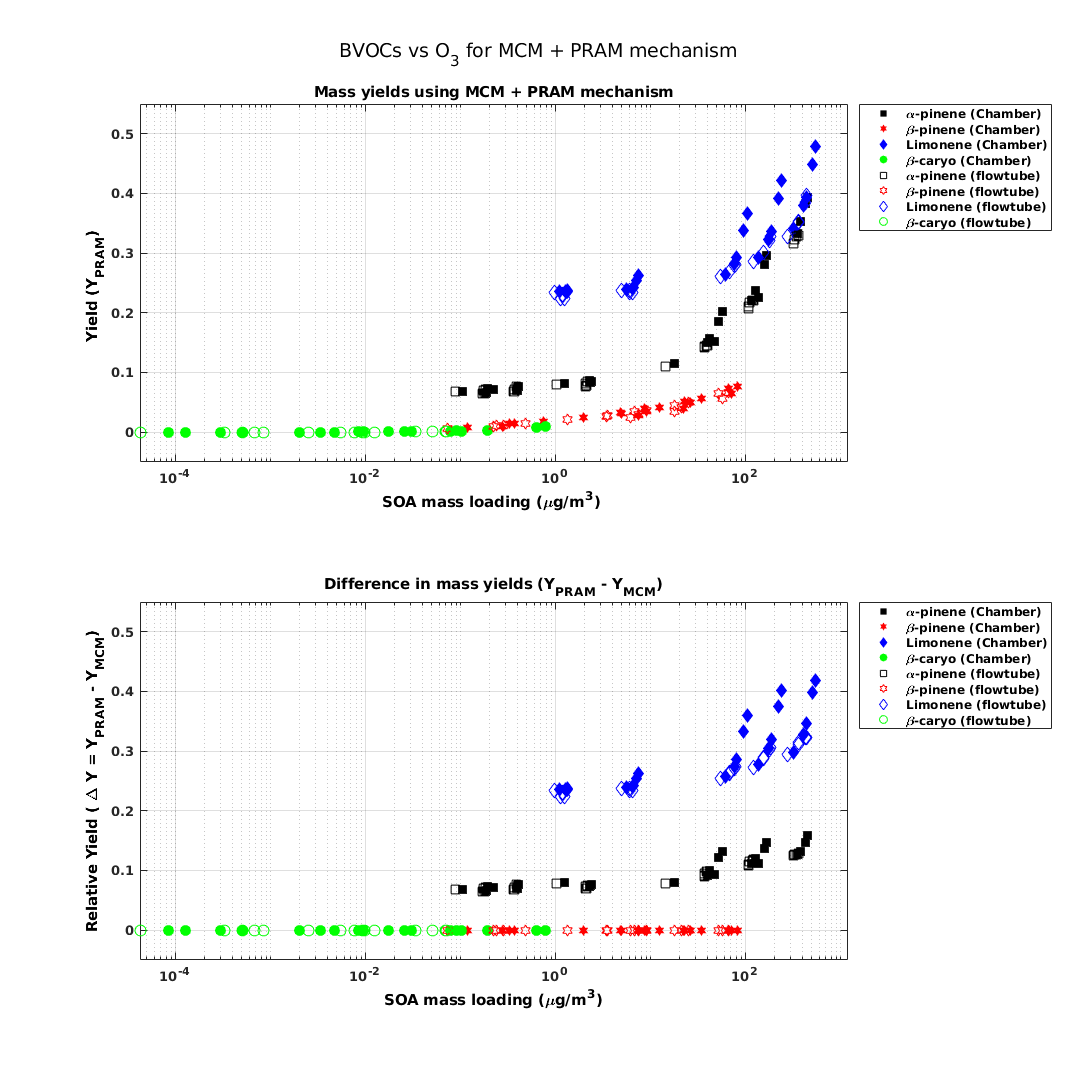

% In use the following function
% data_read_plot, apinene_plot.m

 
close all
clear all 
clc

nn = 2;
cc = 1;



path_hom_cham   = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Chamber_runs/Hom_res/main_res' ;
path_mcm_cham   = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Chamber_runs/Mcm_res/main_res_mcm' ;
path_no_runs    = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Chamber_runs/NO_runs/no_hom' ;
path_temp_runs  = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Chamber_runs/Temp_runs/temp_hom' ;

apin_hom    = load([path_hom_cham,'/ch_hom_apin.dat']);
bcar_hom    = load([path_hom_cham,'/ch_hom_bcar.dat']);
lim_hom     = load([path_hom_cham,'/ch_hom_lim.dat']);
iso_hom     = load([path_hom_cham,'/ch_hom_iso.dat']);
bpin_hom    = load([path_hom_cham,'/ch_hom_bpin.dat']);

apin_mcm    = load([path_mcm_cham,'/ch_mcm_apin.dat']);
bcar_mcm    = load([path_mcm_cham,'/ch_mcm_bcar.dat']);
lim_mcm     = load([path_mcm_cham,'/ch_mcm_lim.dat']);
iso_mcm     = load([path_mcm_cham,'/ch_mcm_iso.dat']);
bpin_mcm    = load([path_mcm_cham,'/ch_mcm_bpin.dat']);

path_hom_ft   = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Flow_tube_runs/Hom_runs/ft_hom' ;
path_mcm_ft   = '/home/local/carltonx/Work/Malte_box/Project_runs/Final_Results/Results/Flow_tube_runs/Mcm_runs/ft_mcm' ;


apin_hom_ft    = load([path_hom_ft,'/ft_apin.dat']);
bcar_hom_ft    = load([path_hom_ft,'/ft_bcar.dat']);
lim_hom_ft     = load([path_hom_ft,'/ft_lim.dat']);
iso_hom_ft     = load([path_hom_ft,'/ft_iso.dat']);
bpin_hom_ft    = load([path_hom_ft,'/ft_bpin.dat']);

apin_mcm_ft    = load([path_mcm_ft,'/ft_apin.dat']);
bcar_mcm_ft    = load([path_mcm_ft,'/ft_bcar.dat']);
lim_mcm_ft     = load([path_mcm_ft,'/ft_lim.dat']);
iso_mcm_ft     = load([path_mcm_ft,'/ft_iso.dat']);
bpin_mcm_ft    = load([path_mcm_ft,'/ft_bpin.dat']);

%% chamber 
iapi_o3      =find(apin_hom(:,3) ~= 0);
iapi_oh      =find(apin_hom(:,2) ~= 0);
iapi_no      =find(apin_hom(:,4) ~= 0);

iiso_o3      =find(iso_hom(:,3) ~= 0);
iiso_oh      =find(iso_hom(:,2) ~= 0);
iiso_no      =find(iso_hom(:,4) ~= 0);

ilim_o3      =find(lim_hom(:,3) ~= 0);
ilim_oh      =find(lim_hom(:,2) ~= 0);
ilim_no      =find(lim_hom(:,4) ~= 0);

ibca_o3      =find(bcar_hom(:,3) ~= 0);
ibca_oh      =find(bcar_hom(:,2) ~= 0);
ibca_no      =find(bcar_hom(:,4) ~= 0);

Na         = 6.022E23; % [#/mol] 
ch_air     = 2.47E19 ;

% apin
Coa_ap_h   = (apin_hom(:,6)./100).*(apin_hom(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_ap_h  = apin_hom(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_ap_h     = Coa_ap_h./dcoa_ap_h; % in percentage 

Coa_ap_m   = (apin_mcm(:,6)./100).*(apin_mcm(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_ap_m  = apin_mcm(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_ap_m   = Coa_ap_m./dcoa_ap_m; % in percentage 


% bpin
Coa_bp_h   = (bpin_hom(:,6)./100).*(bpin_hom(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bp_h  = bpin_hom(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_bp_h     = Coa_bp_h./dcoa_bp_h; % in percentage 

Coa_bp_m   = (bpin_mcm(:,6)./100).*(bpin_mcm(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bp_m  = bpin_mcm(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_bp_m   = Coa_bp_m./dcoa_bp_m; % in percentage 


% lim
Coa_li_h   = (lim_hom(:,6)./100).*(lim_hom(:,5)*136.24*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_li_h  = lim_hom(:,5)*136.24*12.187./293.15;  %ug/m3 reacted VOC
amf_li_h     = Coa_li_h./dcoa_li_h; % in percentage 

Coa_li_m   = (lim_mcm(:,6)./100).*(lim_mcm(:,5)*136.24*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_li_m  = lim_mcm(:,5)*136.24*12.187./293.15;  %ug/m3 reacted VOC
amf_li_m   = Coa_li_m./dcoa_li_m; % in percentage 


% bcary 
Coa_bc_h   = (bcar_hom(:,6)./100).*(bcar_hom(:,5)*204.36*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bc_h  = bcar_hom(:,5)*204.36*12.187./293.15;  %ug/m3 reacted VOC
amf_bc_h     = Coa_bc_h./dcoa_bc_h; % in percentage 

Coa_bc_m   = (bcar_mcm(:,6)./100).*(bcar_mcm(:,5)*204.36*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bc_m  = bcar_mcm(:,5)*204.36*12.187./293.15;  %ug/m3 reacted VOC
amf_bc_m   = Coa_bc_m./dcoa_bc_m; % in percentage 

% isop
Coa_is_h   = (iso_hom(:,6)./100).*(iso_hom(:,5)*68.12*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_is_h  = iso_hom(:,5)*68.12*12.187./293.15;  %ug/m3 reacted VOC
amf_is_h     = Coa_is_h./dcoa_is_h; % in percentage 

Coa_is_m   = (iso_mcm(:,6)./100).*(iso_mcm(:,5)* 68.12 *12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_is_m  = iso_mcm(:,5)*68.12*12.187./293.15;  %ug/m3 reacted VOC
amf_is_m   = Coa_is_m./dcoa_is_m; % in percentage 

%% flowtube
iapi_o3_ft      =find(apin_hom_ft(:,3) ~= 0);
iapi_oh_ft      =find(apin_hom_ft(:,2) ~= 0);
iapi_no_ft      =find(apin_hom_ft(:,4) ~= 0);

iiso_o3_ft      =find(iso_hom_ft(:,3) ~= 0);
iiso_oh_ft      =find(iso_hom_ft(:,2) ~= 0);
iiso_no_ft      =find(iso_hom_ft(:,4) ~= 0);

ilim_o3_ft      =find(lim_hom_ft(:,3) ~= 0);
ilim_oh_ft      =find(lim_hom_ft(:,2) ~= 0);
ilim_no_ft      =find(lim_hom_ft(:,4) ~= 0);

ibca_o3_ft      =find(bcar_hom_ft(:,3) ~= 0);
ibca_oh_ft      =find(bcar_hom_ft(:,2) ~= 0);
ibca_no_ft      =find(bcar_hom_ft(:,4) ~= 0);


% apin
Coa_ap_h_ft   = (apin_hom_ft(:,6)./100).*(apin_hom_ft(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_ap_h_ft  = apin_hom_ft(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_ap_h_ft   = Coa_ap_h_ft./dcoa_ap_h_ft; % in percentage 


Coa_ap_m_ft   = (apin_mcm_ft(:,6)./100).*(apin_mcm_ft(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_ap_m_ft  = apin_mcm_ft(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_ap_m_ft   = Coa_ap_m_ft./dcoa_ap_m_ft; % in percentage 


% bpin
Coa_bp_h_ft   = (bpin_hom_ft(:,6)./100).*(bpin_hom_ft(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bp_h_ft  = bpin_hom_ft(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_bp_h_ft   = Coa_bp_h_ft./dcoa_bp_h_ft; % in percentage 

Coa_bp_m_ft   = (bpin_mcm_ft(:,6)./100).*(bpin_mcm_ft(:,5)*136.23*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bp_m_ft  = bpin_mcm_ft(:,5)*136.23*12.187./293.15;  %ug/m3 reacted VOC
amf_bp_m_ft   = Coa_bp_m_ft./dcoa_bp_m_ft; % in percentage 


% lim
Coa_li_h_ft   = (lim_hom_ft(:,6)./100).*(lim_hom_ft(:,5)*136.24*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_li_h_ft  = lim_hom_ft(:,5)*136.24*12.187./293.15;  %ug/m3 reacted VOC
amf_li_h_ft   = Coa_li_h_ft./dcoa_li_h_ft; % in percentage 

Coa_li_m_ft   = (lim_mcm_ft(:,6)./100).*(lim_mcm_ft(:,5)*136.24*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_li_m_ft  = lim_mcm_ft(:,5)*136.24*12.187./293.15;  %ug/m3 reacted VOC
amf_li_m_ft   = Coa_li_m_ft./dcoa_li_m_ft; % in percentage 


% bcary 
Coa_bc_h_ft   = (bcar_hom_ft(:,6)./100).*(bcar_hom_ft(:,5)*204.36*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bc_h_ft  = bcar_hom_ft(:,5)*204.36*12.187./293.15;  %ug/m3 reacted VOC
amf_bc_h_ft     = Coa_bc_h_ft./dcoa_bc_h_ft; % in percentage 

Coa_bc_m_ft   = (bcar_mcm_ft(:,6)./100).*(bcar_mcm_ft(:,5)*204.36*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_bc_m_ft  = bcar_mcm_ft(:,5)*204.36*12.187./293.15;  %ug/m3 reacted VOC
amf_bc_m_ft   = Coa_bc_m_ft./dcoa_bc_m_ft; % in percentage 

% isop
Coa_is_h_ft   = (iso_hom_ft(:,6)./100).*(iso_hom_ft(:,5)*68.12*12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_is_h_ft  = iso_hom_ft(:,5)*68.12*12.187./293.15;  %ug/m3 reacted VOC
amf_is_h_ft     = Coa_is_h_ft./dcoa_is_h_ft; % in percentage 

Coa_is_m_ft   = (iso_mcm_ft(:,6)./100).*(iso_mcm_ft(:,5)* 68.12 *12.187./293.15) ; %ug/m3 mass conc of organic aerosol in condensed phase
dcoa_is_m_ft  = iso_mcm_ft(:,5)*68.12*12.187./293.15;  %ug/m3 reacted VOC
amf_is_m_ft   = Coa_is_m_ft./dcoa_is_m_ft; % in percentage 


%%  o3 
figure('Position',[1 1 1600 1600]); %( x,y)
clf
box on
set(gca, 'fontsize', [15], 'linewidth', [2])
hold all

subplot(2,1,1)
h   = scatter(Coa_ap_h(iapi_o3), amf_ap_h(iapi_o3), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
h   = scatter(Coa_bp_h(iapi_o3), amf_bp_h(iapi_o3), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_o3), amf_li_h(ilim_o3), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_o3), amf_bc_h(ibca_o3), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;

h   = scatter(Coa_ap_h_ft(iapi_o3_ft), amf_ap_h_ft(iapi_o3_ft), 70, 's' ,'k');hold on;
h   = scatter(Coa_bp_h_ft(iapi_o3_ft), amf_bp_h_ft(iapi_o3_ft), 70, 'h' ,'r');hold on;
h   = scatter(Coa_li_h_ft(ilim_o3_ft), amf_li_h_ft(ilim_o3_ft), 70, 'd' ,'b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_o3_ft), amf_bc_h_ft(ibca_o3_ft), 70, 'o' ,'g');hold on;
% h   = scatter(Coa_is_h(iiso_o3), amf_is_h(iiso_o3), 40, 'filled','^' ,'MarkerFaceColor','c');hold on;


set(gca,'xscale','log')
grid on
box on
   lh = legend({'\alpha-pinene (Chamber)','\beta-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)',...
        '\alpha-pinene (flowtube)','\beta-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)',});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');  
%  set(gca,'xticklabel',[10^-4,10^-2,10^0,10^2,])
xlim([0,1200])
ylim([-0.05,0.55]) 
title('Mass yields using MCM + PRAM mechanism' )
xlabel('SOA mass loading (\mug/m^3) ','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Yield (Y_P_R_A_M) ','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')


subplot(2,1,2)


h   = scatter(Coa_ap_h(iapi_o3), (amf_ap_h(iapi_o3)-amf_ap_m(iapi_o3)), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
h   = scatter(Coa_bp_h(iapi_o3), (amf_bp_h(iapi_o3)-amf_bp_m(iapi_o3)), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_o3), (amf_li_h(ilim_o3)-amf_li_m(ilim_o3)), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_o3), (amf_bc_h(ibca_o3)-amf_bc_m(ibca_o3)), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;
% h   = scatter(Coa_is_m(iiso_o3), (amf_is_h(iiso_o3)-amf_is_m(iiso_o3)), 40, 'filled','^' ,'MarkerFaceColor','c');hold on;

h   = scatter(Coa_ap_h_ft(iapi_o3_ft), (amf_ap_h_ft(iapi_o3_ft)-amf_ap_m_ft(iapi_o3_ft)), 70,'s','k');hold on;
h   = scatter(Coa_bp_h_ft(iapi_o3_ft), (amf_bp_h_ft(iapi_o3_ft)-amf_bp_m_ft(iapi_o3_ft)), 70,'h','r');hold on;
h   = scatter(Coa_li_h_ft(ilim_o3_ft), (amf_li_h_ft(ilim_o3_ft)-amf_li_m_ft(ilim_o3_ft)), 70,'d','b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_o3_ft), (amf_bc_h_ft(ibca_o3_ft)-amf_bc_m_ft(ibca_o3_ft)), 70,'o','g');hold on;

set(gca,'xscale','log')
grid on
box on
 lh = legend({'\alpha-pinene (Chamber)','\beta-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)',...
        '\alpha-pinene (flowtube)','\beta-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)',});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');
 xlim([0,1200])
ylim([-0.05,0.55]) 
title('Difference in mass yields (Y_P_R_A_M - Y_M_C_M)' )
xlabel('SOA mass loading (\mug/m^3)','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Relative Yield ( \Delta Y = Y_P_R_A_M - Y_M_C_M)','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')



suptitle('BVOCs vs O_3 for MCM + PRAM mechanism')

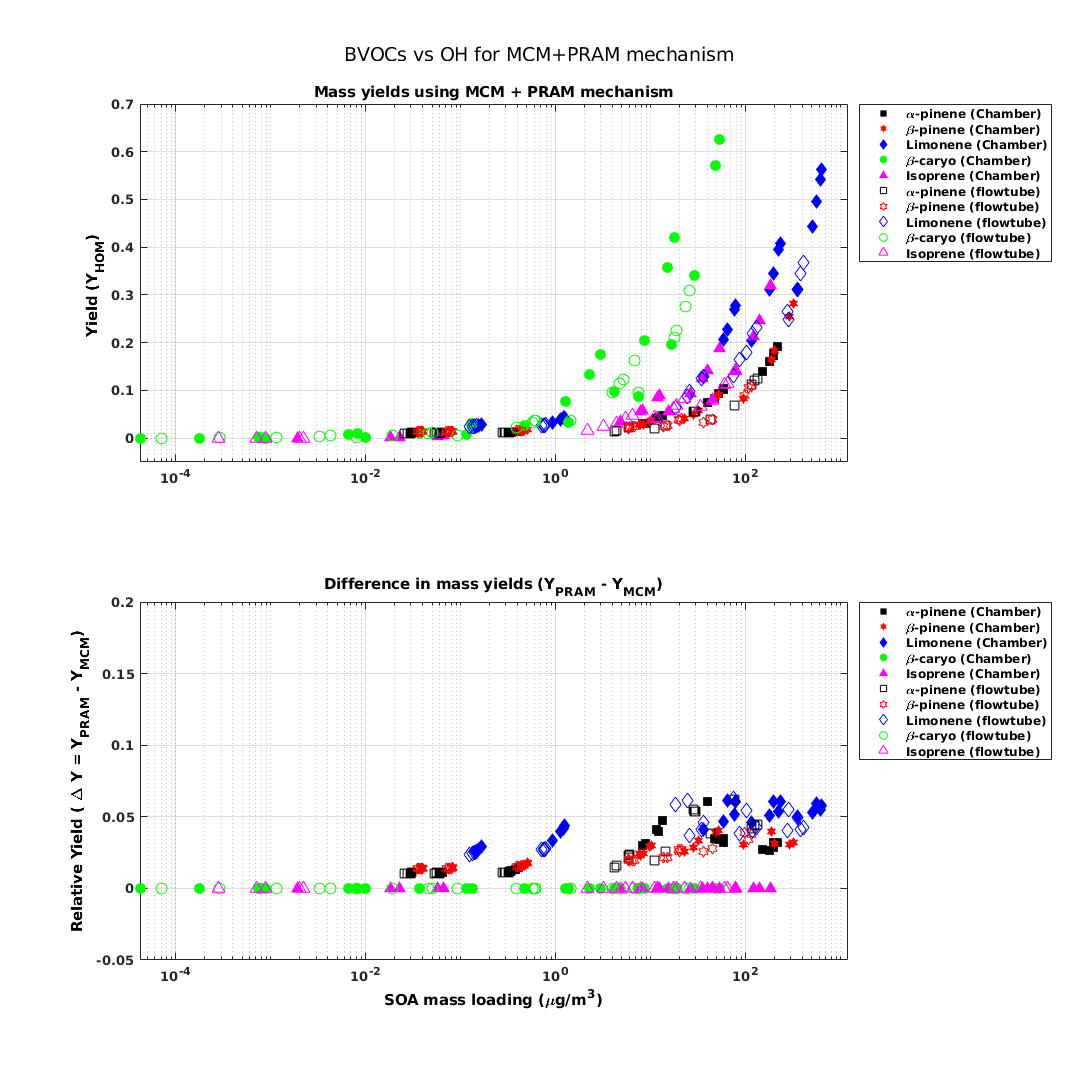


% filename = ['/home/carltonx/Work/Paper 1/Plots/all_data_o3_ft.png'];
%  
%  saveas(gcf,filename)
 
%%  oh 
figure('Position',[1 1 1600 1600]); %( x,y)
clf
box on
set(gca, 'fontsize', [15], 'linewidth', [2])
hold all

subplot(2,1,1)
h   = scatter(Coa_ap_h(iapi_oh), amf_ap_h(iapi_oh), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
h   = scatter(Coa_bp_h(iapi_oh), amf_bp_h(iapi_oh), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_oh), amf_li_h(ilim_oh), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_oh), amf_bc_h(ibca_oh), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;
h   = scatter(Coa_is_h(iiso_oh), amf_is_h(iiso_oh), 70, 'filled','^' ,'MarkerFaceColor','m');hold on;


h   = scatter(Coa_ap_h_ft(iapi_oh_ft), amf_ap_h_ft(iapi_oh_ft), 70,'s' ,'k');hold on;
h   = scatter(Coa_bp_h_ft(iapi_oh_ft), amf_bp_h_ft(iapi_oh_ft), 70,'h' ,'r');hold on;
h   = scatter(Coa_li_h_ft(ilim_oh_ft), amf_li_h_ft(ilim_oh_ft), 70,'d' ,'b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_oh_ft), amf_bc_h_ft(ibca_oh_ft), 70,'o' ,'g');hold on;
h   = scatter(Coa_is_h_ft(iiso_oh_ft), amf_is_h_ft(iiso_oh_ft), 70,'^' ,'m');hold on;

set(gca,'xscale','log')
grid on
box on

  lh = legend({'\alpha-pinene (Chamber)','\beta-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)','Isoprene (Chamber)',...
        '\alpha-pinene (flowtube)','\beta-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)','Isoprene (flowtube)'});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');
 ylim([-0.05,0.7]) 
xlim([0,1200])
% set(gca,'xscale','log')
% grid on
% box on

title('Mass yields using MCM + PRAM mechanism' )
% xlabel('SOA mass loading (\mug/m^3) ','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Yield (Y_H_O_M) ','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')


subplot(2,1,2)


h   = scatter(Coa_ap_h(iapi_oh), (amf_ap_h(iapi_oh)-amf_ap_m(iapi_oh)), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
h   = scatter(Coa_bp_h(iapi_oh), (amf_bp_h(iapi_oh)-amf_bp_m(iapi_oh)), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_oh), (amf_li_h(ilim_oh)-amf_li_m(ilim_oh)), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_oh), (amf_bc_h(ibca_oh)-amf_bc_m(ibca_oh)), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;
h   = scatter(Coa_is_h(iiso_oh), (amf_is_h(iiso_oh)-amf_is_m(iiso_oh)), 70, 'filled','^' ,'MarkerFaceColor','m');hold on;


h   = scatter(Coa_ap_h_ft(iapi_oh_ft), (amf_ap_h_ft(iapi_oh_ft)-amf_ap_m_ft(iapi_oh_ft)), 70, 's' ,'k');hold on;
h   = scatter(Coa_bp_h_ft(iapi_oh_ft), (amf_bp_h_ft(iapi_oh_ft)-amf_bp_m_ft(iapi_oh_ft)), 70, 'h' ,'r');hold on;
h   = scatter(Coa_li_h_ft(ilim_oh_ft), (amf_li_h_ft(ilim_oh_ft)-amf_li_m_ft(ilim_oh_ft)), 70, 'd' ,'b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_oh_ft), (amf_bc_h_ft(ibca_oh_ft)-amf_bc_m_ft(ibca_oh_ft)), 70, 'o' ,'g');hold on;
h   = scatter(Coa_is_h_ft(iiso_oh_ft), (amf_is_h_ft(iiso_oh_ft)-amf_is_m_ft(iiso_oh_ft)), 70, '^' ,'m');hold on;

set(gca,'xscale','log')
grid on
box on

  lh = legend({'\alpha-pinene (Chamber)','\beta-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)','Isoprene (Chamber)',...
        '\alpha-pinene (flowtube)','\beta-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)','Isoprene (flowtube)'});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 
%  set(lh,'Position', newPosition,'Units', newUnits);
set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');
 xlim([0,1200])
ylim([-0.05,0.2]) 
title('Difference in mass yields (Y_P_R_A_M - Y_M_C_M)' )
xlabel('SOA mass loading (\mug/m^3)','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Relative Yield ( \Delta Y = Y_P_R_A_M - Y_M_C_M)','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')
suptitle('BVOCs vs OH for MCM+PRAM mechanism')

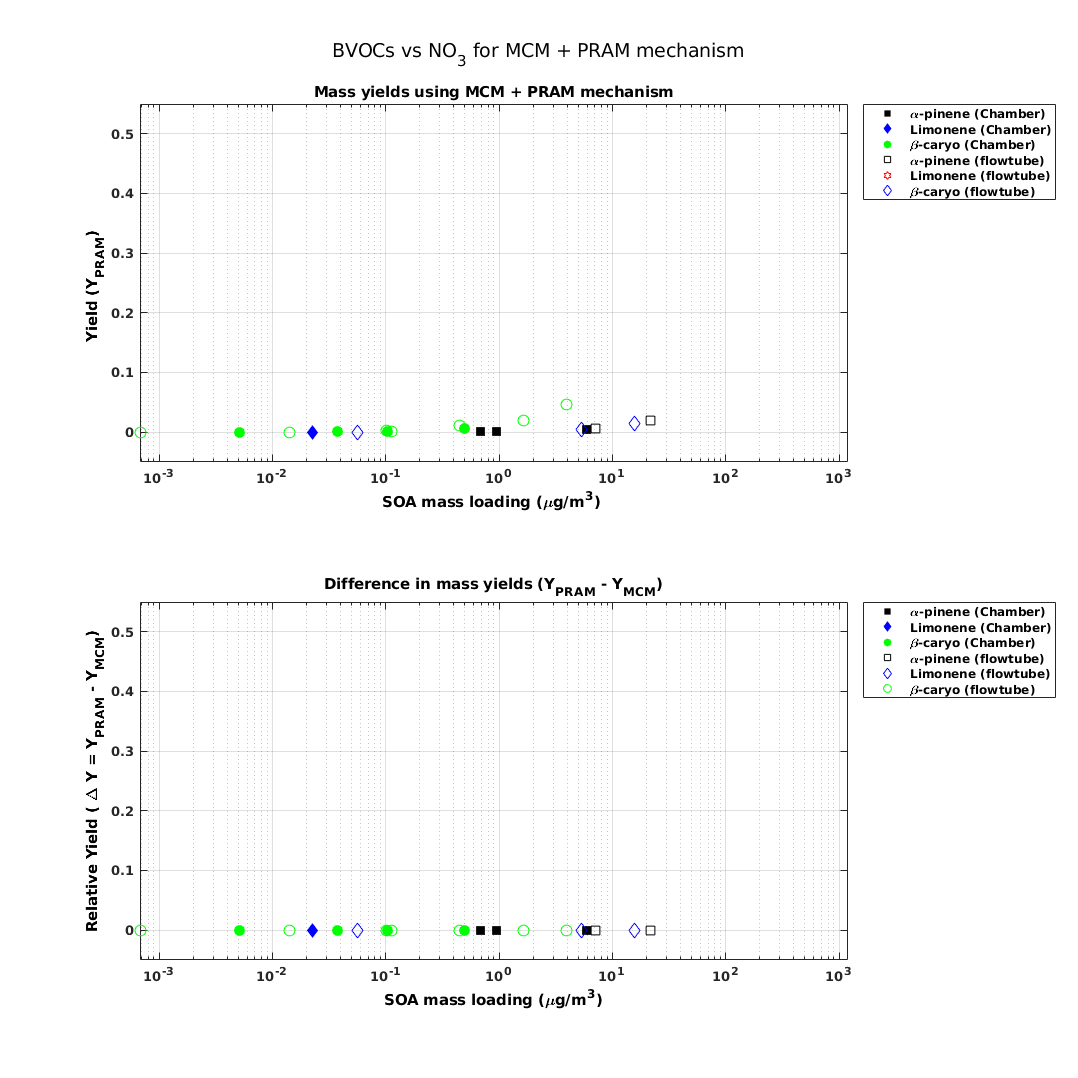


% filename = ['/home/carltonx/Work/Paper 1/Plots/all_data_oh_ft.png'];
%  
% saveas(gcf,filename)

%% NO3
figure('Position',[1 1 1600 1600]); %( x,y)
clf
box on
set(gca, 'fontsize', [15], 'linewidth', [2])
hold all

subplot(2,1,1)
h   = scatter(Coa_ap_h(iapi_no), amf_ap_h(iapi_no), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
% h   = scatter(Coa_bp_h(iapi_no), amf_bp_h(iapi_no), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_no), amf_li_h(ilim_no), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_no), amf_bc_h(ibca_no), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;

h   = scatter(Coa_ap_h_ft(iapi_no_ft), amf_ap_h_ft(iapi_no_ft), 70, 's' ,'k');hold on;
h   = scatter(Coa_bp_h_ft(iapi_no_ft), amf_bp_h_ft(iapi_no_ft), 70, 'h' ,'r');hold on;
h   = scatter(Coa_li_h_ft(ilim_no_ft), amf_li_h_ft(ilim_no_ft), 70, 'd' ,'b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_no_ft), amf_bc_h_ft(ibca_no_ft), 70, 'o' ,'g');hold on;
% h   = scatter(Coa_is_h(iiso_o3), amf_is_h(iiso_o3), 40, 'filled','^' ,'MarkerFaceColor','c');hold on;


set(gca,'xscale','log')
grid on
box on
   lh = legend({'\alpha-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)',...
        '\alpha-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)',});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');  
%  set(gca,'xticklabel',[10^-4,10^-2,10^0,10^2,])
xlim([0,1200])
ylim([-0.05,0.55]) 
title('Mass yields using MCM + PRAM mechanism' )
xlabel('SOA mass loading (\mug/m^3) ','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Yield (Y_P_R_A_M) ','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')


subplot(2,1,2)


h   = scatter(Coa_ap_h(iapi_no), (amf_ap_h(iapi_no)-amf_ap_m(iapi_no)), 70, 'filled','s' ,'MarkerFaceColor','k');hold on;
% h   = scatter(Coa_bp_h(iapi_no), (amf_bp_h(iapi_no)-amf_bp_m(iapi_no)), 70, 'filled','h' ,'MarkerFaceColor','r');hold on;
h   = scatter(Coa_li_h(ilim_no), (amf_li_h(ilim_no)-amf_li_m(ilim_no)), 70, 'filled','d' ,'MarkerFaceColor','b');hold on;
h   = scatter(Coa_bc_h(ibca_no), (amf_bc_h(ibca_no)-amf_bc_m(ibca_no)), 70, 'filled','o' ,'MarkerFaceColor','g');hold on;
% h   = scatter(Coa_is_m(iiso_o3), (amf_is_h(iiso_o3)-amf_is_m(iiso_o3)), 40, 'filled','^' ,'MarkerFaceColor','c');hold on;

h   = scatter(Coa_ap_h_ft(iapi_no_ft), (amf_ap_h_ft(iapi_no_ft)-amf_ap_m_ft(iapi_no_ft)), 70,'s','k');hold on;
% h   = scatter(Coa_bp_h_ft(iapi_no_ft), (amf_bp_h_ft(iapi_no_ft)-amf_bp_m_ft(iapi_no_ft)), 70,'h','r');hold on;
h   = scatter(Coa_li_h_ft(ilim_no_ft), (amf_li_h_ft(ilim_no_ft)-amf_li_m_ft(ilim_no_ft)), 70,'d','b');hold on;
h   = scatter(Coa_bc_h_ft(ibca_no_ft), (amf_bc_h_ft(ibca_no_ft)-amf_bc_m_ft(ibca_no_ft)), 70,'o','g');hold on;

set(gca,'xscale','log')
grid on
box on
 lh = legend({'\alpha-pinene (Chamber)','Limonene (Chamber)','\beta-caryo (Chamber)',...
        '\alpha-pinene (flowtube)','Limonene (flowtube)','\beta-caryo (flowtube)',});
 newPosition = [0.8 0.475 0.01 0.075];
 newUnits = 'normalized';
 set(lh,'Position', newPosition,'Units', newUnits,'Location','NorthEastOutside');
 xlim([0,1200])
ylim([-0.05,0.55]) 
title('Difference in mass yields (Y_P_R_A_M - Y_M_C_M)' )
xlabel('SOA mass loading (\mug/m^3)','FontSize',15,'FontWeight','bold','Color','k')
ylabel('Relative Yield ( \Delta Y = Y_P_R_A_M - Y_M_C_M)','FontSize',15,'FontWeight','bold','Color','k')
set(gca,'FontSize',10,'FontWeight','bold')



suptitle('BVOCs vs NO_3 for MCM + PRAM mechanism')